**1. PARAMETERS**

Nbits = 440;                                            % Number of bits to be simulated
Rb = 10e3;                                              % Bit rate [b/s]
Fc = 1e6;                                               % Carrier frequency [Hz]
M = 4;                                                  % Modulation order
dev = 2.5e3;                                            % Inner frequency deviation [Hz]
osf = 20;                                               % Baseband oversampling factor
span = 8;                                               % Span for Gaussian filter representation [S] (only GFSK)
sps = 8;                                                % Number of samples per symbol for Gaussian filter representation [Sa/S] (only GFSK)
BT = 0.5;                                               % 3dB bandwidth - symbol time product (only GFSK)

Rs = Rb/log2(M);                                        % Symbol rate [S/s]
h = 2*(M-1)*dev/Rs;                                     % Modulation index
FsBB = osf*Rs;                                          % Baseband sample rate [Sa/s]
TsBB = 1/FsBB;                                          % Baseband sample period [s]
FsRF = 12*Fc;                                           % RF sample rate [Sa/s]

WaveBBxlim = 1e-3;                                      % Limit on X-axis for BB waveform plot [s]
SpectBBxlim = FsBB/2e3;                                 % Limit on X-axis for BB spectrum plot [kHz]
SpectBBylim = -120;                                     % Limit on Y-axis for BB spectrum plot [dBW]
SpanRFxlim = 10*Rs;                                     % Span on X-axis for RF spectrum plot [Hz]
SpectRFylim = -110;                                     % Limit on Y-axis for RF spectrum plot [dBW]
Blue = [.2 .2 1];                                       % Custom blue color
Green = [.2 .8 .2];                                     % Custom green color
Orange = [1 .7 .2];                                     % Custom orange color
Violet = [.8 0 .8];                                     % Custom violet color
Azure = [0 .8 .8];                                      % Custom azure color
Red = [1 .2 0];                                         % Custom red color
Brown = [.5 .2 0];                                      % Custom brown color





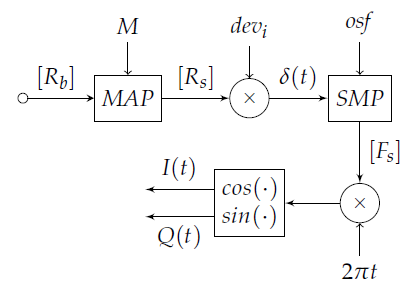


$$S_{\mathit{RF}}(t) = cos\Big(2\pi t\delta(t)\Big)\! \cdot cos\Big(2\pi F_c t\Big)-\, sin\Big(2\pi t\delta(t)\Big)\! \cdot sin\Big(2\pi F_c t\Big)$$


[*Wikipedia link*](https://en.wikipedia.org/wiki/Frequency-shift_keying)

**2. FSK PROCESSING**

[Symbs,Nsymbs] = GetSymbs(Nbits,M);                                         % Retrieve random symbols stream and its length
FskSamps = dev*repelem(Symbs,osf);                                          % Multiply symbols for inner deviation and oversample
TimeBB = TsBB*(0:Nsymbs*osf-1);                                             % Time axis for BB waveform
FskWaveI = cos(2*pi*FskSamps.*TimeBB);                                      % In-phase part of the FSK baseband waveform
FskWaveQ = sin(2*pi*FskSamps.*TimeBB);                                      % Quadrature part of the FSK baseband waveform
FskSgnBB = FskWaveI+1i*FskWaveQ;                                            % FSK complex baseband signal
[FskFreqBB,FskSpectBB,~] = GetSpect(FskSgnBB,FsBB);                           % FSK baseband signal power spectrum
TimeRF = 0:1/FsRF:TimeBB(end);                                              % Time axis for RF waveform
FskSgnRF = spline(TimeBB,FskWaveI,TimeRF).*cos(2*pi*Fc*TimeRF) ...          % FSK radio-frequency signal
    -spline(TimeBB,FskWaveQ,TimeRF).*sin(2*pi*Fc*TimeRF);
[FskFreqRF,FskSpectRF,~] = GetSpect(FskSgnRF,FsRF);                           % FSK radio-frequency signal power spectrum

fprintf('Modulation order = %d',M);

Modulation order = 4

fprintf('Data rate = %1.1f kHz',Rb/1e3);

Data rate = 10.0 kHz

fprintf('Modulation index = %1.1f',h);

Modulation index = 3.0

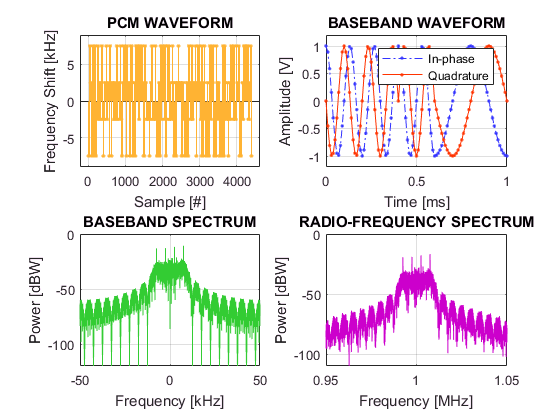


figure('Name','FSK','NumberTitle','off'); subplot(2,2,1)
stem(0:Nsymbs*osf-1,FskSamps/1e3,'.','Color',Orange)
axis([Nsymbs*osf*[-0.05 1.05] (M-1)*dev*1.2/1e3*[-1 1]])
title('PCM WAVEFORM'); grid on
xlabel('Sample [#]'); ylabel('Frequency Shift [kHz]')

subplot(2,2,2); hold on; box on
plot(TimeBB*1e3,FskWaveI,'.-.','Color',Blue)
plot(TimeBB*1e3,FskWaveQ,'.-','Color',Red)
xlabel('Time [ms]'); ylabel('Amplitude [V]'); grid on
axis([0 WaveBBxlim*1e3 -1.2 1.2]); hold off
title('BASEBAND WAVEFORM'); legend(' In-phase',' Quadrature')

subplot(2,2,3);
plot(FskFreqBB/1e3,FskSpectBB,'Color',Green)
xlabel('Frequency [kHz]'); ylabel('Power [dBW]')
axis([SpectBBxlim*[-1 1] SpectBBylim 0])
title('BASEBAND SPECTRUM'); grid on

subplot(2,2,4);
plot(FskFreqRF/1e6,FskSpectRF,'Color',Violet)
xlabel('Frequency [MHz]'); ylabel('Power [dBW]')
axis([(SpanRFxlim*[-1 1]+Fc)/1e6 SpectRFylim 0])
title('RADIO-FREQUENCY SPECTRUM'); grid on

**3. FUNCTIONS**

function [ OutSymbs, SymbLen ] = GetSymbs( Nbits, M )

%     rng(76)
    TxBits = randi([0 1],1,Nbits);
        
    L = log2(M);                                        % Number of bits per symbol
    GrayMtx = zeros(M,L);                               % Gray mapping matrix
    LastCell = [0;1];
    GrayMtx(1:2,end) = LastCell;
    for i = 2:L
        GrayMtx(1+2^(i-1):2^i,end-i+2:end) = flipud(LastCell);
        GrayMtx (1+2^(i-1):2^i,end-i+1) = 1;
        LastCell = GrayMtx(1:2^i,end-i+1:end);
    end
    
    GrayMap = zeros(1,M);
    for i = 1:M
        j = 0;
        while j <= M
            if j == bi2de(GrayMtx(i,:),'left-msb')
                GrayMap(i) = j;
                break;
            else
                j = j+1;
            end
        end
    end
    
    SymbLen = Nbits/L;
    OutSymbs = zeros(1,SymbLen);
    MinVal = 1-2^L;
    for i = 1:SymbLen
        OutSymbs(i) = GrayMap(bi2de(TxBits(1+(i-1)*L:i*L),'left-msb')+1);
        OutSymbs(i) = MinVal+2*OutSymbs(i);
    end

end


function [ FreqAx, PwrSpect, OvPwrF ] = GetSpect( Sgn, Fs )
    Ns = length(Sgn);                                                           % Length (in samples) of the input waveform
    dF = Fs/Ns;                                                                 % Discretization step for frequency axis
    FreqAx = -Fs/2:dF:Fs/2-dF;                                                  % Frequency axis for spectrum plot
    CpxSpect = fftshift(fft(Sgn))/Ns;                                           % Complex spectrum
    PwrSpect = 20*log10(abs(CpxSpect));                                         % Power spectrum [dBW/Hz]
    OvPwrF = 10*log10(sum((abs(CpxSpect)).^2));                                 % Overall signal power [dBW] estimated in frequency domain (NB: do NOT multiply by dF, that's wrong for this descrete representation!)
    % as a check, below overall power is estimated in time as well %
%     OvPwrT = 10*log10(sum(Sgn.^2)/length(Sgn));                                 % Overall signal power [dBW] estimated in time domain (i.e. P = Vrms^2/R, where Vrms = sqrt(1/N*sum(Sgn[i]^2)) and assuming R = 1 Ohm)
end


% Function for integrating the input signal (specifying also its sample period)
function [ OutSamps ] = Integrator( InSamps, Ts )

    IntegrNum = 1;                                          % Numerator taps of integrator
    IntegrDen = [1 -1];                                     % Denominator taps of integrator (1st order IIR)
    OutSamps = filter(Ts*IntegrNum,IntegrDen,InSamps);
    
end


% Function for filtering the input signal by means of Gaussian taps and
% adding/removing proper delay samples.
function [ OutSamps ] = GaussFilter( InSamps, BT, span, sps )
    
    GaussTaps = gaussdesign(BT,span,sps);               % Retrieve Gaussian filter taps
    GaussDelay = span*sps/2;
    OutSamps = filter(GaussTaps,1,[InSamps zeros(1,GaussDelay)]);
    OutSamps = OutSamps(1+GaussDelay:end);
    
end